**Translación en la Frecuencia**

%%Aplicando las propiedades 
clear all;
close all;
clc;
% Espectro de magnitud Original
Fs = 500;       %Frecuencia de muestreo
t = -1:1/Fs:2;  %Vector de tiempo
L = 1000;       %Longitud de la señal 
A = 3;          %Escalar
X = A*((4/3)*t-2/3);%Señal multiplicada por escalar
Y= fft(X,L)   %Transformada rápida

Y = 	1.0e+03 *

  -2.0040 + 0.0000i  -0.0040 + 1.2732i  -0.0040 + 0.6366i  -0.0040 + 0.4244i  -0.0040 + 0.3183i  -0.0040 + 0.2546i  -0.0040 + 0.2122i  -0.0040 + 0.1819i  -0.0040 + 0.1591i  -0.0040 + 0.1414i  -0.0040 + 0.1273i  -0.0040 + 0.1157i  -0.0040 + 0.1061i  -0.0040 + 0.0979i  -0.0040 + 0.0909i  -0.0040 + 0.0848i  -0.0040 + 0.0795i  -0.0040 + 0.0748i  -0.0040 + 0.0707i  -0.0040 + 0.0669i  -0.0040 + 0.0636i  -0.0040 + 0.0605i  -0.0040 + 0.0578i  -0.0040 + 0.0553i  -0.0040 + 0.0530i  -0.0040 + 0.0508i  -0.0040 + 0.0489i  -0.0040 + 0.0470i  -0.0040 + 0.0454i  -0.0040 + 0.0438i  -0.0040 + 0.0423i  -0.0040 + 0.0409i  -0.0040 + 0.0397i  -0.0040 + 0.0384i  -0.0040 + 0.0373i  -0.0040 + 0.0362i  -0.0040 + 0.0352i  -0.0040 + 0.0343i  -0.0040 + 0.0333i  -0.0040 + 0.0325i  -0.0040 + 0.0317i  -0.0040 + 0.0309i  -0.0040 + 0.0301i  -0.0040 + 0.0294i  -0.0040 + 0.0288i  -0.0040 + 0.0281i  -0.0040 + 0.0275i  -0.0040 + 0.0269i  -0.0040 + 0.0263i  -0.0040 + 0.0258i


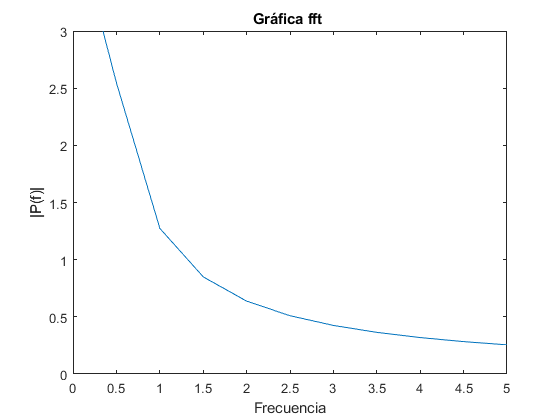


P = abs(Y/Fs);
f = linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica fft ')
xlabel('Frecuencia')
ylabel('|P(f)|')

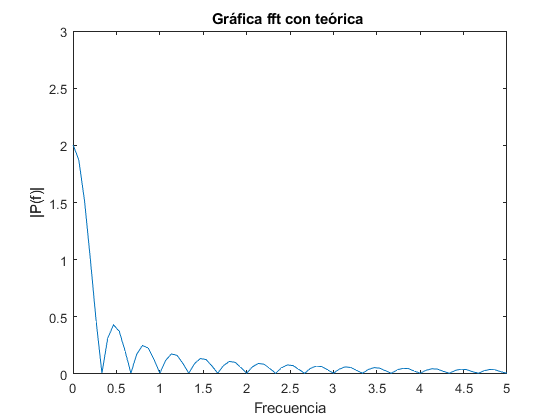


%Traslación en frecuencia
Fs = 200;       %Frecuencia de muestreo
t = -1:1/Fs:2;  %Vector de tiempo
L = 3000;       %Longitud de la señal 
A = 360;          %Escalar
Tras_f =((4/3)*(exp(1i*t*A))-2/3);%S
Y= fft(Tras_f,L);    %Transformada rápida

P = abs(Y/Fs);
f = linspace(0,Fs,numel(P));

plot(f,P)
axis ([0 5 0 3])
title('Gráfica fft con teórica ')
xlabel('Frecuencia')
ylabel('|P(f)|')

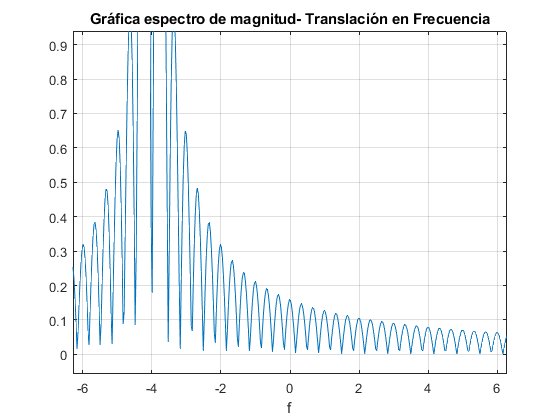



syms t f;       %Variables simbólicas
e=-4;
x=exp(2*pi*1i*t*e)*((4/3)*t-2/3);  %
%x=(((4/3)*exp(1i*t*e))-2/3);  %
Tras_f=int(x*exp(-1i*2*pi*f*t),t,-1,2); %Transformada de Fourier teórica
%hold on         %sobreposición
% fplot(f,abs(Tras_f))
% title('Variación de la Frecuencia')
% figure

%-----Gráfica espectro de magnitud
ezplot(abs(Tras_f));
title('Gráfica espectro de magnitud- Translación en Frecuencia')
grid on

Espectro